# Algoritmos Numéricos por Computadora

# Tercer parcial - Primavera 2020

Cambia el nombre del script a Nombre (ej: Marcelo).

Sube tu archivo resultado a comunidad $\to$ Examen final antes de las 18:55 pm del martes 3 de junio.

- **Cuando yo abra o pruebe tu script deben desplegarse en la pantalla todos los resultados. **

- **Debes escribir al final del script todas las funciones que uses.**

- **El examen es individual, debes resolverlo sin ayuda de ninguna persona. **

- **Revisa con mucho cuidado tus respuestas. El examen será calificado de manera muy estricta.**

## 1. Uso eficiente de un lenguaje de programación matricial 

1.1   Calcula (en una línea) la norma euclidiana de un vector v. Verifica tu resultado usando la función norm, un vector cualquiera y la funcion isequal.

%

$$val = \sqrt{\pi^{2}-2\,\psi^{\prime }(\frac{20003}{2})}$$

1.2 Calcula  $\sqrt{8\sum_{i=0}^{10000} \frac{1}{{\left(2n+1\right)}^2 }}$   (en dos o menos líneas)

syms k
val=sqrt(8*symsum(1/(2*k+1)^2,k,0,10000))

1.3 Determina (en una línea) si una matriz es positiva definida: cuadrada, simétrica y con todos sus valores propios positivos. Verifica tu respuesta con las matrices: [2,2;2,5] y [2,4;4,5]

%

1.4 Se tiene un vector de n elementos. Escribe el código necesario para agregar un nuevo valor al vector, recorriendo los primeros valores (perdiendo el primero)  e insertando el nuevo valor en la última posición. Ejemplo, si v=[1,2,3,4], al agregar el 5 se tiene v=[2,3,4,5].

%

Puedes (debes) usar este código en la respuesta de la pregunta 3.

## 2. Errores numéricos de las soluciones computacionales

2.1 En la siguiente operación, ¿por que el resultado no es verdadero (1)? 

res = 7/100*100 - 7;
isequal(res,0)

2.2 ¿A qué es igual res en la pregunta anterior? (Hint: la respuesta tiene que ver con la resolución de Matlab en el rango de valores de 7)

isequal(res, x) 

% 

2.3 El método de encripción RSA usa dos llaves, una pública (n,e) y una privada (n,d), y se basa en la siguiente igualdad matemática para encriptar y desencriptar un mensaje m

 ${\left(m^e \right)}^d =m={\left(m^d \right)}^e$  (donde las operaciones se hacen módulo n).

Por ejemplo, para encriptar letras minúsculas (ASCII)

n=33;
e=3;
d=7;
m = 'v';                        % letra a transmitir
ms = double(m) - double('a');   % mensaje ms<n            
c = mod(ms^d,n);                % mensaje encriptado
mr = mod(c^e,n);                % mensaje desencriptado
str = char(mr + double('a')) 
isequal(ms,mr)                  % letra transmitida = letra recibida

Sin embargo, si usamos las siguentes llaves podemos no desencriptar correctamente el mensaje :(

Caso favorable, m='b'

n=35;
e=5;
d=29;
m = 'b';                        
ms = double(m) - double('a');   
c = mod(ms^d,n);
eps(ms^d)
mr = mod(c^e,n);
isequal(ms,mr)

Caso desfavorable, m='v'

n=35;
e=5;
d=29;
m = 'v';                        
ms = double(m) - double('a');   
c = mod(ms^d,n);
eps(ms^d)
mr = mod(c^e,n);
isequal(ms,mr)

Explica por qué pasa esto (Hint: ¿qué error numérico se presenta? ¿Por qué?)

% 

## 3. Entendimiento del funcionamiento de métodos numéricos

Para mejorar la exactitud del método ABM, pueden usarse las siguientes fórmulas.

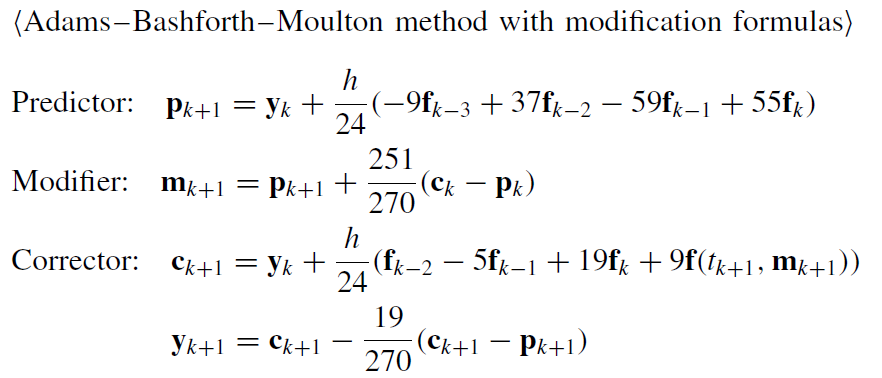

AL final de este script codifica el método mejorado (ABM4mo) utilizando estas fórmulas y minimizando el número de evaluaciones de la función f y minimizando la cantidad de memoria utilizada.

Escribe y prueba tu método por partes:

3.1 Codifica el método para *f* escalar

3.2 Codifica el método para *f* vectorial

3.3 Codifica el método guardando los valores calculados de* f* en un vector (matriz)

3.4 Codifica el método guardando solo los últimos 4 valores calculados de* f* (y los últimos 2 de *p* y de *c*).

Al final, solo deja en el script tu mejor solución.

Prueba tu función en cada parte resolviendo el siguiente problema de valor inicial (usa h=0.05):

$y^{\prime } =f\left(x,y\right)=\frac{1}{2}\left(1+x\right)y^2$         $y\;\left(0\right)=1$          t in [0,1]

Grafica la solución.

%

## 4. Solución de ecuaciones diferenciales y sistemas lineales

Usando el método de diferencias finitas, resuelve el siguiente problema de valores en la frontera:


$$7\frac{d^2 }{\mathrm{d}x^2 }y-2\frac{d}{\mathrm{d}x}y-y+t=0$$
         
$$y\left(0\right)=5\;,\;\;y\;\left(20\right)=8$$


4.1 Escribe las fórmulas de diferencias finitas (centrales)  para la segunda y primera derivadas $O\left(h^2 \right)$

4.2 Plantea el sistema de ecuaciones lineales correspondiente (con 100 puntos).

%

4.3 Resuelve el sistema de ecuaciones lineales de manera eficiente

%

4.4 Grafica la solución *y(t)*.

%